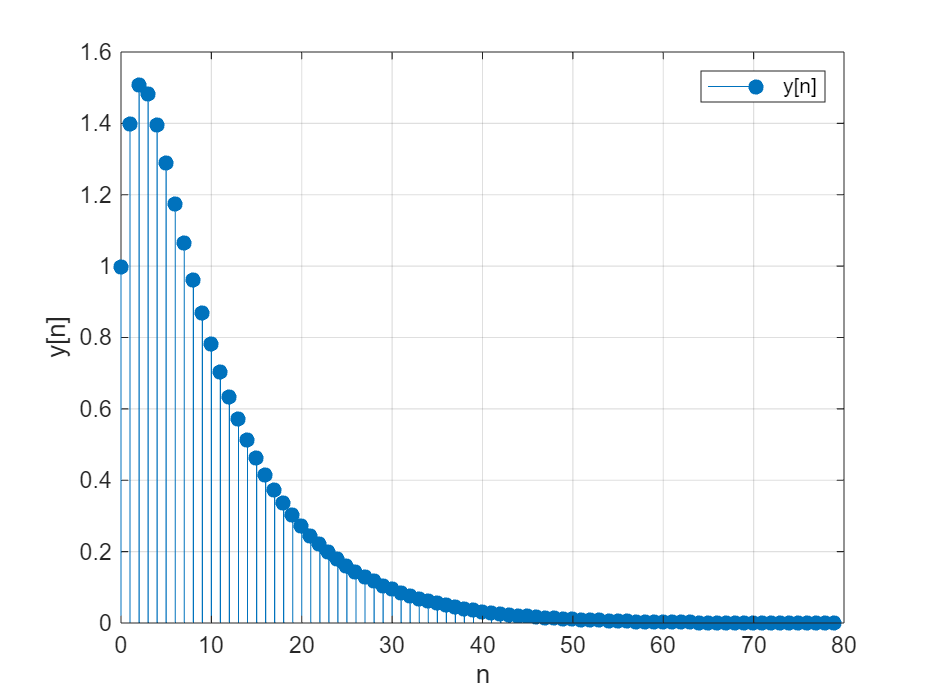

figure
 xn4 = 0:79;
 xn = 0.9.^xn4;
hn = 0.5.^xn4;
 zn = conv([xn xn],hn);
 time2 = 0;
 for i = 0:1:49
    f = @()(conv([xn xn],hn));
    t_timeie2 = timeit(f);
    time2 = time2+t_timeie2;
 end
 yn=zn(81:160);
 stem(xn4,yn,'filled');
 grid on
 xlabel('n');
 ylabel('y[n]')
 legend('y[n]')

 fprintf('执行时间（秒）： %.6f\n', time2/50);

执行时间（秒）： 0.000002


 f80c = time2/50

f80c = 1.9819e-06